Water Jacket

Non End

# 1. JFT160  

보통  mk는 매틀랩에서 변수 만드는 함수면

create 는  app 프로그램내에서 객체 만드는 함수(물론 매틀랩에 테이블도 만듬)

Solid GeomSet

 Origin Solid

 FaceExtrud Solid

Total Solid Set

Face Set

1. End

1)Circuit 에서 Coil End Component로 구사

2)3D Model에서 구현후 R로 구현 (JCR) - Motorcad 참조 

2. Cooling

1)JCF는 유사

2)JCR에 따라 Oil Spray & Water Cooling 구분 

## CreateGeomFaceExtrudeSolid

devCreateGeomFaceExtrudeSolid(doublearray,PartName,geomApp)

## Input Variable and calcThermalSubVariable

tempThermalInputVariable
calcThermalSubVariable
scaleFactor =           64.81481481481


%  createJmagGeomSet(geomApp)
%  getEdgeItemFromString(testString)
% mk
%  mkfaceSetListTable()
%  mkEdgeItem

## 1. Create Geom Set

### 1) get AssemTable

% getGeomAssemItemListTable
AssemTable=getGeomAssemItemListTable(geomApp)
geomApp.Hide

### 2) add AssemPartDataTable

% getSGeomPartData
% AssemPartStruct=struct();
for AssemItemIndex=1:height(AssemTable)
    if ~contains(AssemTable.AssemItemName{AssemItemIndex},'Plane')
    AssemTable.AssemPartTable{AssemItemIndex}=getSGeomPartData(geomApp,AssemTable.AssemItemName{AssemItemIndex})
    end
end


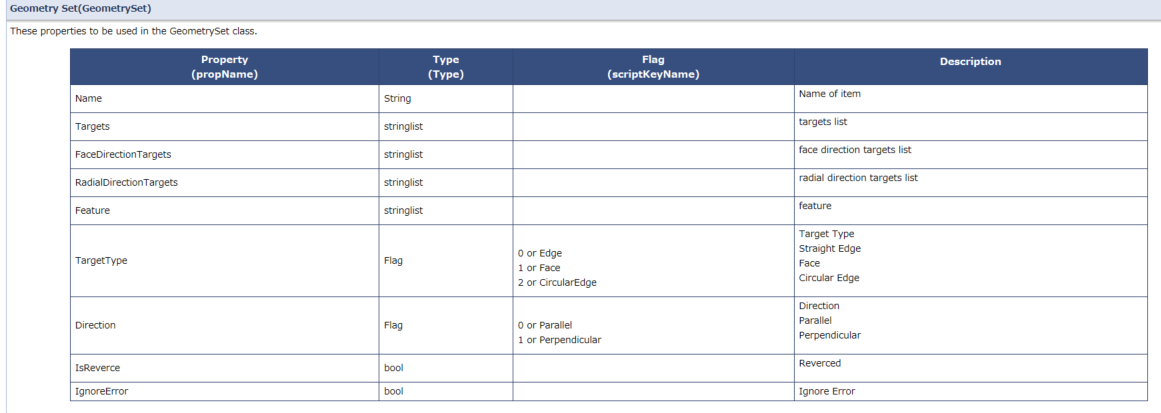

### 3) [TC]Geom Set List 2 AssemTable

%  [TC] mkGeomSetListTable() % TBC Outer Rotor Case
% [TC] 
for AssemTableIndex=1:height(AssemTable)
    PartName=AssemTable.AssemItemName{AssemTableIndex}
    GeomSetListTable=mkGeomSetListTable(PartName,'Inner')
    AssemTable.GeomSetList{AssemTableIndex}=GeomSetListTable;
end
%  getEdgeItemFromString(testString)
% mk
%  mkEdgeItem

### 3) [TC] CreateJmagGeomSet

% [TC] createJmagGeomSet(geomApp)

% AssemTable=addGeomSetList2AssemTable(AssemTable,geomApp)
for AssemTableIndex=1:height(AssemTable)
    newGeomSetTable=createJmagGeomSet(AssemTable.GeomSetList{AssemTableIndex},geomApp)
    AssemTable.GeomSetTable{AssemTableIndex}=newGeomSetTable;
end


### 1)[TB] Solid GeomSet

Origin Solid -[WIP] Origin Solid face두번?

% SolidIdentifierName = "lump(TExtrudeSolid306+face(TExtrudeSolid306+face(TRegionItem305)))"
% SolidIdentifierName= "lump(TFaceExtrudeSolid308+lump(TExtrudeSolid306+face(TExtrudeSolid306+face(TRegionItem305))))"


clear ExtrudeSolidList
for PartTableIndex=1:height(AssemPartStruct(1).AssemPartTable)
tempSolidId=unique(extractBetween(AssemPartStruct(1).AssemPartTable.IdentifierName{PartTableIndex},'TExtrudeSolid','+'))
    if ~isempty(tempSolidId)
    ExtrudeSolidList{PartTableIndex,1}=tempSolidId{:}
    else
    ExtrudeSolidList{PartTableIndex,1}='empty'
    end
end
ExtrudeSolidList=removeCellwithMatchingStr(ExtrudeSolidList,'empty')
ExtrudeSolidList=unique(ExtrudeSolidList)




FaceExtrude  Solid

clear FaceExtrudeSolidList
for PartTableIndex=1:height(AssemPartStruct(1).AssemPartTable)
tempSolidId=unique(extractBetween(AssemPartStruct(1).AssemPartTable.IdentifierName{PartTableIndex},'TFaceExtrudeSolid','+'))
    if ~isempty(tempSolidId)
    FaceExtrudeSolidList{PartTableIndex,1}=tempSolidId{:}
    else
    FaceExtrudeSolidList{PartTableIndex,1}='empty'
    end
end
FaceExtrudeSolidList=removeCellwithMatchingStr(FaceExtrudeSolidList,'empty')
FaceExtrudeSolidList=unique(FaceExtrudeSolidList)


Total Solid Set

find(contains(AssemPartStruct(1).AssemPartTable.IdentifierName,subIdentifierName))
find(strcmp(AssemPartStruct(1).AssemPartTable.IdentifierName,subIdentifierName))

IdentifierName=AssemPartStruct(1).AssemPartTable.IdentifierName{1}
% mkSubIdName4RegionExtrude
% mkSolidIdentifierName
splitedIdNameCell=splitGeomIdName(IdentifierName)


### 2)[TB] Face GeomSet

 DevdetSolidGeomSetType()

% Stator
refarray[0] = u"face(TExtrudeSolid306+edge(TExtrudeSolid306+edge(TRegionItem305+TSketchArc290)))"
refarray[0] = u"face(TFaceExtrudeSolid308+edge(TFaceExtrudeSolid308+edge(TExtrudeSolid306+edge(TExtrudeSolid306+edge(TRegionItem305+TSketchArc290)))))"



%[3D가 되서 face가 된 부분(2d에서는 edge) : face - edge +edge
refarray[0] = u"face(TExtrudeSolid484+edge(TExtrudeSolid484+edge(TRegionItem483+TSketchArc466)))"
refarray[0] = u"face(TExtrudeSolid484+edge(TExtrudeSolid484+edge(TRegionItem483+TSketchLine459)))"
refarray[0] = u"face(TFaceExtrudeSolid486+edge(TFaceExtrudeSolid486+edge(TExtrudeSolid484+edge(TExtrudeSolid484+edge(TRegionItem483+TSketchArc466)))))"

%[2D에서 원래 Region]인 surface 쪽 :        face + face (RegionItem)
refarray[0] = u"face(TExtrudeSolid484+face(TExtrudeSolid484+face(TRegionItem483)))"
refarray[0] = u"face(TFaceExtrudeSolid486+face(TFaceExtrudeSolid486+face(TExtrudeSolid484+face(TExtrudeSolid484+face(TRegionItem483)))))"




% mkfaceSetListTable
% Rotor Face



mkBodySetListTable

createJmagGeomSet


## 2. [TB]Creating the Designer TP sets


% Template Parameter Set

% Coil
TParameterSetName=[PartName,'Coil-Stator Core Face']               
%TParameterSetName=% Stator Core , Rotor, Coil End
TParameterSetName=[PartName,'Front Face']                        
TParameterSetName=[PartName,'Back Face']                         
% TParameterSetName=%PartName Stator Core , Roto
TParameterSetName=[PartName,'Gap Face']                          
% TParameterSetName=%PartName Stator Cor
TParameterSetName=[PartName,'Side Face']                         
% TParameterSetName=%PartName Rotor
TParameterSetName=[PartName,'Magnet-Core Face']                   
TParameterSetName=[PartName,'Core-Shaft Face']                    

% Create Set
app.GetModel("IPM").GetSetList().GetSet(TParameterSetName).SetUpdateByRelation(True)
app.GetModel("IPM").GetSetList().GetSet(TParameterSetName).SetMatcherType("Selection")
app.GetModel("IPM").GetSetList().GetSet(TParameterSetName).ClearParts()
sel = app.GetModel("IPM").GetSetList().GetSet(TParameterSetName).GetSelection()



## 3. Setting Equation & Setting Circuit 

### 1 Gap (  1Gap(Resistor) + 2 FEM)

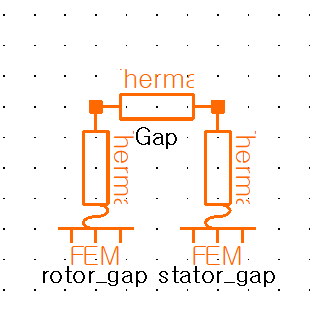

#### Thermal Resistor/

로터와 고정자처럼 분리된 두 물체 사이에 열이 전달되는 경우 열 회로의 열 저항 부품을 사용합니다. 

두 물체 사이에 상당히 얇은 간격이나 코팅과 같은 단열재를 통해 열이 전달되는 경우 접촉 열 저항 조건을 사용합니다.

% Gap - Thermal Resistor - Cooling (Forced Convection )
% * scaleFactor
Steady2=app.GetModel("JFT160ThermalParametricScale_2").GetStudy("SteadyCoilEndForcedCool_1e-2_1e-3")
Steady2.GetCircuit().GetComponent("Gap").SetValue("Characteristic Length", [num2str(stack_length),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("GapWidth", [num2str(gap_length),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("RotorRadius", [num2str(rotor_radius),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("ThermalResistorArea", "1*gap_area")
Steady2.GetCircuit().GetComponent("Gap").SetValue("ThermalCorrection", "1*1")
Steady2.GetCircuit().GetComponent("Gap").SetValue("FlowVelocity", "1*74418.05")


###  2 Housing (1 Cap+3 Resistor + 1 Convection + 1FEM)

General Contact

Cooling Water jacket

Thermal Conduction (Cylinder)

C_Housing

Natural & or Constant Resistance

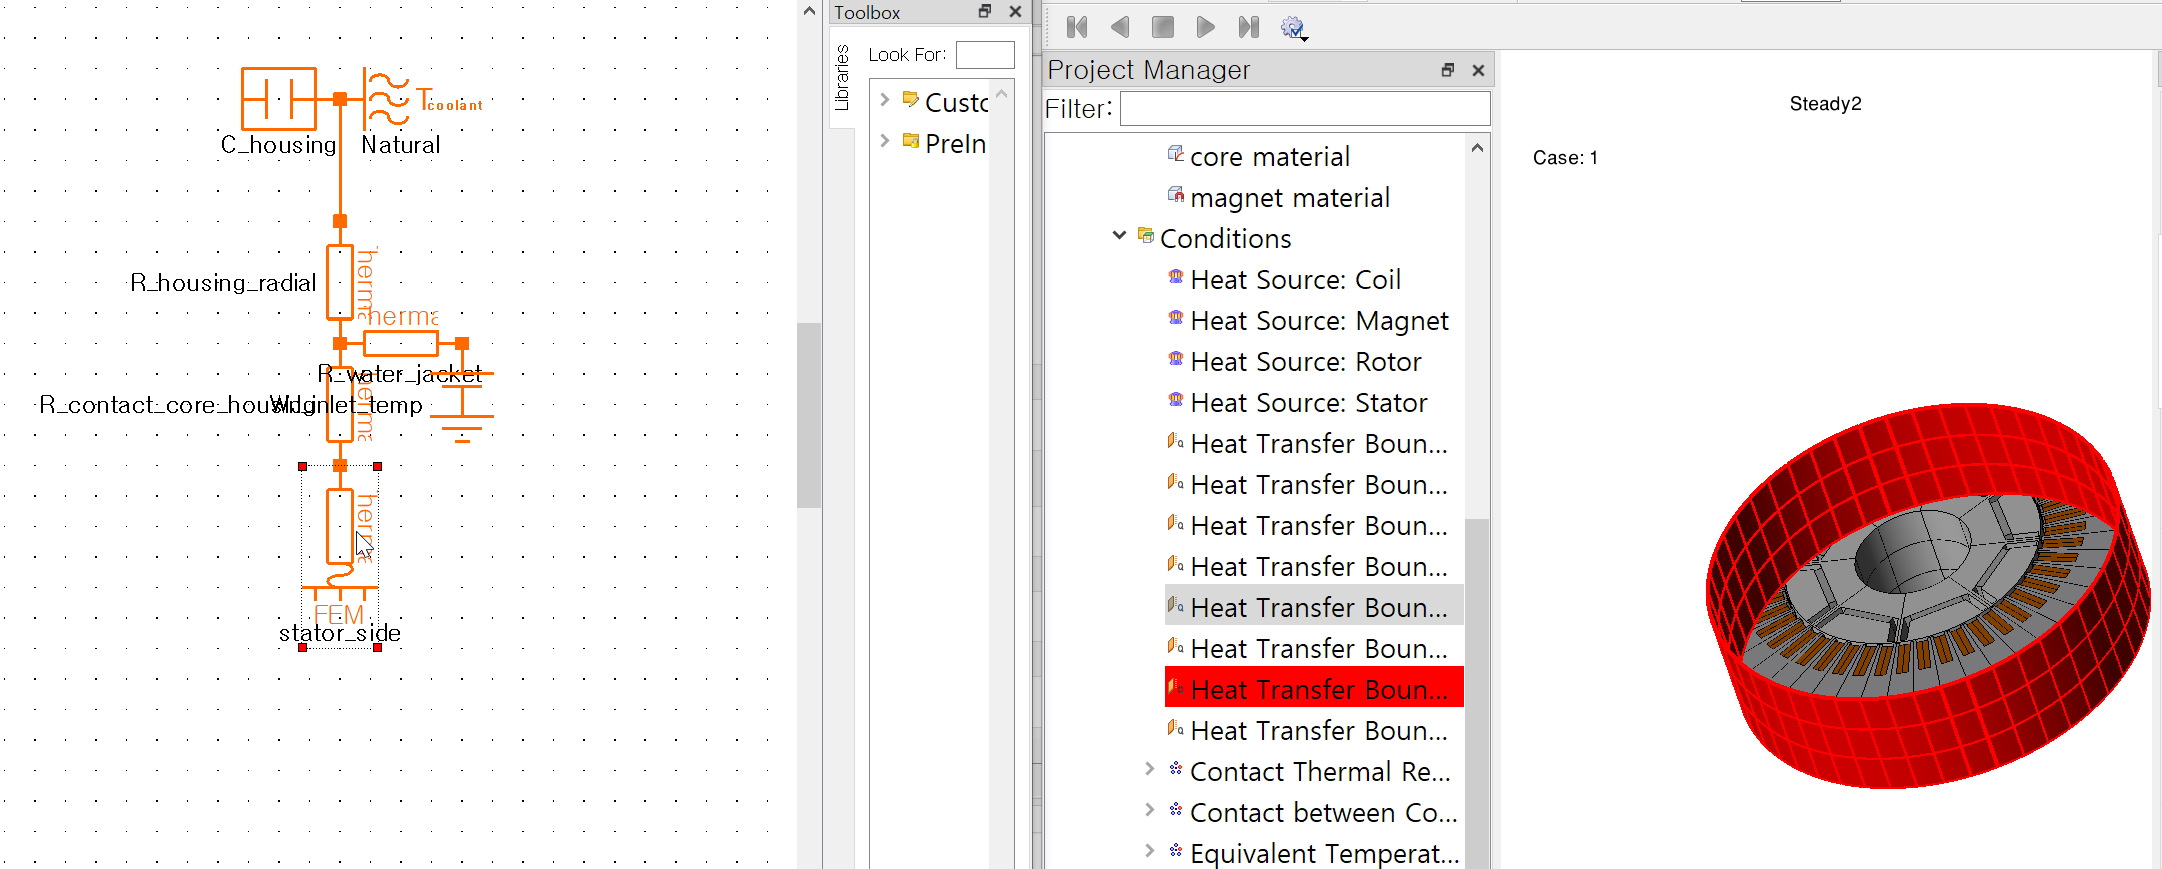

1.R_contact_core_housing 

Housing 과 접하는 Core 접촉저항 설정

#### Thermal Resistor (contact & conduction & Convection

% R_contact_core_housing 
% General Contact
Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalConductivity", 0.02)
Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalCorrection", 4)
Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalResistorArea", "stator_side_area")

% c.f calcRthGenContact
% housing_Core_ThermalConductivity=0.02
% stator_side_area=3543359;
% RthHousingCore = calcRthGenContact(4, 0.01, housing_Core_ThermalConductivity, 3543359)  % degC/W

% 7 Cooling Water jacket 
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("FlowVelocity",           num2str(WJ_velocity))
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeNumber", num2str(WJ_tube_number))
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeWidth",  [num2str(WJ_tube_width), '*scaleFactor'])
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeHeight", [num2str(WJ_tube_height),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeRadius", [num2str(WJ_tube_radius),'*scaleFactor'])


% c.f RthWaterJacket
% HTC_water=14000
% RthWaterJacket = calcRthWaterJacket(4, HTC_water, WJ_tube_radius, WJ_tube_width, WJ_tube_number)

%  R_housing_radial
% Thermal Conduction (Cylinder)
% set Equation 
addJMAGEqaution("Housing_height",[num2str(housing_height),'*scaleFactor'],Steady2)
addJMAGEqaution("Housing_outer_radius",[num2str(Housing_outer_radius),'*scaleFactor'],Steady2)
addJMAGEqaution("Housing_inner_radius",[num2str(Housing_inner_radius),'*scaleFactor'],Steady2)
addJMAGEqaution("TC_housing",[num2str(housing_conductivity)],Steady2)
% set Thermal Resistor with  Thermal Conduction (Cylinder)
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorCylinderHeight", "Housing_height")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalCorrection", 1)
% c.f Cylinder Resistance
% RthHousingRadial = calcRthRadial(1, housing_conductivity, housing_height*scaleFactor,  Housing_outer_radius*scaleFactor,Housing_inner_radius*scaleFactor)

#### Heat Capacity

- C Housing

#### 
$$$C=C_F \rho C_p V$$$



$$$C$ : Heat capacity $(\mathrm{J} / \mathrm{deg} C)$
$\rho:$ Density of the heat-radiating object $\left(\mathrm{g} / \mathrm{cm}^{\wedge} 3\right)$
$C_p$ : Specific heat of the heat-radiating object $(\mathrm{J} / \mathrm{kg} / \mathrm{deg} \mathrm{C})$
$V$ : Volume of the heat-radiating object $\left(\mathrm{mm}^{\wedge} 3\right)$
$C_F$ : Correction factor (Default: 1)$$


% C_Housing
housing_density              = 7800    
housing_specific_heat        = 450
V_housing = calcHousingVolume(housing_outer_diameter*scaleFactor, housing_inner_diameter*scaleFactor, housing_height*scaleFactor)
C_housing=calcHeatCapa(housing_density,housing_specific_heat,V_housing)
% C_Housing=12759.55*1/4
Steady2.GetCircuit().GetComponent("C_housing").SetValue("HeatCapacity", num2str(C_housing))



#### Convection Cooling

Natural & or Constant Resistance

% Natural & or Constant Resistance
Steady2.GetCircuit().GetComponent("Natural").SetValue("Thermal Area", "2*pi* Housing_outer_radius* Housing_height")
Steady2.GetCircuit().GetComponent("Natural").SetValue("CharacteristicLengthNatural", "Housing_outer_radius *2")

% c.f Constant Resistance
% HTC_air = 10;
% A_housing=calcCylinderArea(housing_height*scaleFactor,housing_outer_diameter*scaleFactor);
% R_housing_to_ambient = 1 / HTC_air / A_housing;



### 3. Part ( 8 Resistor + 1 Cap + 7 FEM)

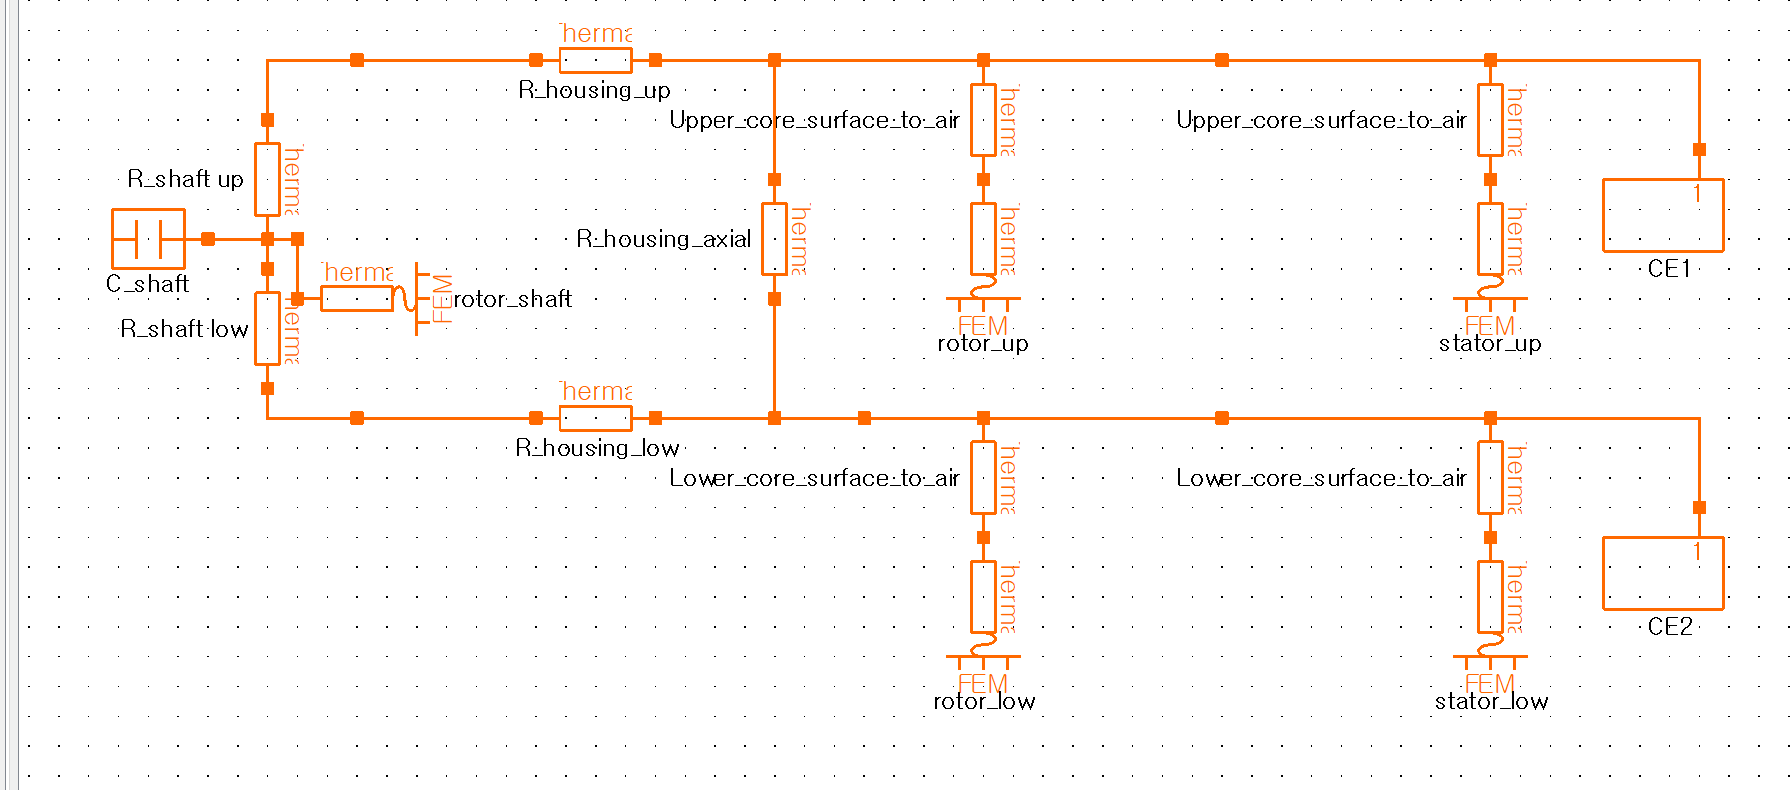

#### rotor Shaft

 FEM- rotor_shaft

R_shaft_up & low

C_shaft

#### Housing

R_housing_up & low

R_housing_axial

#### Core

Upper_core_surface_to_air

FEM rotor up

Lower_core_surface_to_air

FEM rotor low

Upper_core_surface_to_air

FEM stator up

Lower_core_surface_to_air

FEM stator low

 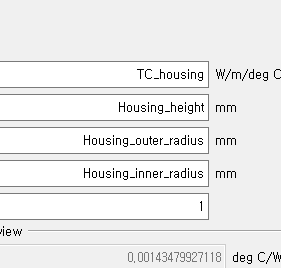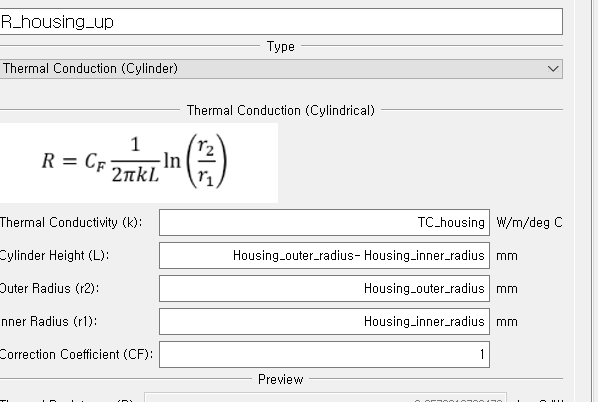

%3 R_shaft up & % 13 R_shaft low
    % Constant Resistance
A_shaft=(pi * (shaft_diameter*scaleFactor / 2)^2 )
R_shaft = calcRthGenContact(1, shaft_length*scaleFactor, shaft_conductivity, A_shaft)
% R_shaft = (1 / shaft_conductivity) * (shaft_length / 1000) / (pi * (shaft_diameter / 2)^2 / 1000000)
R_shaft_up = R_shaft/2;
R_shaft_low = R_shaft/2;
Steady2.GetCircuit().GetComponent("R_shaft up").SetValue("ThermalResistor", num2str(R_shaft_up))
Steady2.GetCircuit().GetComponent("R_shaft_low").SetValue("ThermalResistor", num2str(R_shaft_low))

% C_shaft
V_shaft = (shaft_length*scaleFactor / 1000) * (pi * (shaft_diameter*scaleFactor / 2 / 1000)^2);
C_shaft=calcHeatCapa(shaft_density,shaft_specific_heat,V_shaft)
Steady2.GetCircuit().GetComponent("C_shaft").SetValue("HeatCapacity", num2str(C_shaft))

% 4 R_housing_up
    % Thermal Conduction (Cylinder)
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorCylinderHeight", "Housing_outer_radius-Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalCorrection", 1)
% 14 R_housing low
    % Thermal Conduction (Cylinder)
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorCylinderHeight", "Housing_outer_radius-Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalCorrection", 1)

% 5 R_housing_axial
    % Constant Resistance
% R_housing_axial = (1 / housing_conductivity) * (housing_height / 1000) / (pi * (housing_outer_diameter / 2 / 1000)^2 - pi * (housing_inner_diameter / 2 / 1000)^2);
% A_housing=calcCylinderSideArea(housing_height,housing_outer_diameter);
A_housingTop = calcCircleArea(housing_outer_diameter*scaleFactor, housing_inner_diameter*scaleFactor)
R_housing_axial = calcRthGenContact(1, housing_height*scaleFactor, housing_conductivity, A_housingTop)
Steady2.GetCircuit().GetComponent("R_housing_axial").SetValue("ThermalResistor", R_housing_axial)

% 위처럼 되는 이유 MarginNote 필기 그림 참조 Shaft-> Housing 

% 6 Upper_core_surface_to_air
    % Constant Resistance
RthST2AirUp=(1/HTC_air)/(core_stator_area*SLOTS*3/4/1000000)
% 9 Lower_core_surface_to_air
RthST2AirLow=(1/HTC_air)/(core_stator_area*SLOTS*3/4/1000000)

% (1/HTC_air)/(core_stator_area/1000000)

% 11 Upper_core_surface_to_air
RthRT2AirUp=(1/HTC_air)/(core_rotor_area*POLES/1000000)
RthRT2AirLow=(1/HTC_air)/(core_rotor_area*POLES/1000000)
% 12 Lower_core_surface_to_air

% 10 R_coilend_to_air2
R_coilend_to_air2=Steady2.GetCircuit().GetInstance("R_coilend_to_air2",0)
% R_coilend_to_air2.MoveTo(-100,44)

#### Coil End Cooling

% Thermal Resistor
RthCoilEnd=(1/coilend_conductivity)/(coilend_area/1e6)*(coilend_height*scaleFactor/1000)  % [degC/W]
% Heat Capacity
CpCoilEnd=coilend_specific_heat*coilend_density*coilend_area/1e9             % [J/degC]
% Thermal Resistance
RthConvCoilEnd=1/(HTC_air*coilend_surface_area/stack_length*scaleFactor*coilend_height*scaleFactor/1e6)   % [degC/W]

Steady2.GetCircuit().GetComponent("CE1").SetValue("ThermalResistance", RthCoilEnd)
Steady2.GetCircuit().GetComponent("CE1").SetValue("HeatCapacity", CpCoilEnd)
Steady2.GetCircuit().GetComponent("CE1").SetValue("ThermalResistanceCooling1", RthConvCoilEnd)
Steady2.GetCircuit().GetComponent("CE2").SetValue("ThermalResistance", RthCoilEnd)
Steady2.GetCircuit().GetComponent("CE2").SetValue("HeatCapacity", CpCoilEnd)
Steady2.GetCircuit().GetComponent("CE2").SetValue("ThermalResistanceCooling1", RthConvCoilEnd)

app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().AddEquation("Tc_Copper")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetType(0)
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetExpression("400")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetDescription("W/m/degC")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetModeling(False)
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetTrueValue("")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetFalseValue("")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("Tc_Copper").SetDisplayName("Tc_Copper")


app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().AddEquation("heatSpec")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetType(0)
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetExpression("380")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetDescription("specific heat")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetModeling(False)
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetTrueValue("")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetFalseValue("")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetDesignTable().GetEquation("heatSpec").SetDisplayName("heatSpec")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCircuit().GetComponent("Natural").SetValue("Thermal Area", "2*pi* HEIGHT*scaleFactor* SD1*scaleFactor")

## 4. Setting the Contact Thermal Resistance Pattern(Rotation) Condition

app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").CreateCondition("ContactResistanceRotationPattern", "Magnet-Core")
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Magnet-Core").SetValue("ThermalConductivity", 0.02)
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Magnet-Core").SetValue("Thickness", 0.01)
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Magnet-Core").SetValue("NumCopies", "POLES")
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Magnet-Core").ClearParts()
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Magnet-Core").AddSet(app.GetModel("JFT160ThermalParametricScale_0").GetSetList().GetSet("Rotor Magnet-Core Face"), 0)


### Setting Coil and Core Contact Patter(Rotation) 

app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").CreateCondition("CustomContactResistanceRotationPattern", "Coil-Core")
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").SetValue("ContactType", 1)
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").SetValue("InsulationThickness", 0.05)
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").SetValue("Pressure", 0.21)
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").SetValue("NumCopies", "SLOTS")
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").ClearParts()
app.GetModel("JFT160ThermalParametricScale_0").GetStudy("transient").GetCondition("Coil-Core").AddSet(app.GetModel("JFT160ThermalParametricScale_0").GetSetList().GetSet("Coil-Stator Core Face"), 0)



### Setting the Equivalent Temperature Boundary Pattern

### Set Heat Transfer Boundary

app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Rotor_low").SetLink("rotor_low")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Rotor_shaft").SetLink("rotor_shaft")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Rotor_gap").SetLink("rotor_gap")

%
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Stator_up").SetLink("stator_up")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Stator_low").SetLink("stator_low")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Stator_side").SetLink("stator_side")
app.GetModel("JFT160ThermalParametricScale_2").GetStudy("Steady2").GetCondition("Stator_gap").SetLink("stator_gap")


## 3. [WIP]기존 Jmag 2D Project로부터 JCF생성(JFT154참조)

devThermalModelBuildFromJFT154 %[WIP]

#### 3D One Pole

JmagLinkMatlabPath='C:\Program Files\JMAG-Designer22.2\Matlab\9.13'
jmagCommonPath='C:\Program Files\JMAG-Designer22.2\Matlab\Common'

addpath(genpath(JmagLinkMatlabPath))
addpath(genpath(jmagCommonPath))


## 2. Express

Express (devJmagExpress -> 3d?)

devJmagExpress  %[WIP]